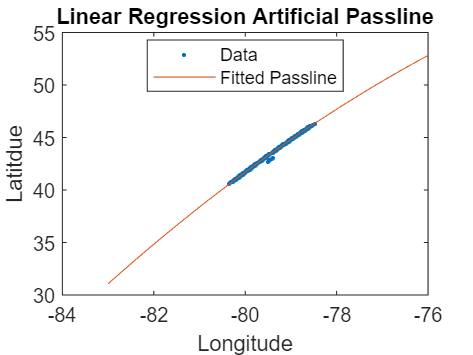

dat = importdata('coords_full.dat');

plot(dat(:, 1), dat(:, 2), '.')
hold on

one = ones(size(dat, 1), 1);
C = [one dat(:, 1) dat(:, 1).^2];

d = dat(:, 2);

beta = C\d;

x = linspace(-83, -76, 100);

f = @(x) beta(1) + x * beta(2) + x.^2 * beta(3) ;

plot(x, f(x))
xlabel("Longitude")
ylabel("Latitdue")
title("Linear Regression Artificial Passline")
legend('Data', 'Fitted Passline','Location','best')
hold off

sigma = sqrt(1/(950-3) * norm(C * beta - d)^2)

sigma = 0.0515

var = sigma^2 * inv(C' *C);

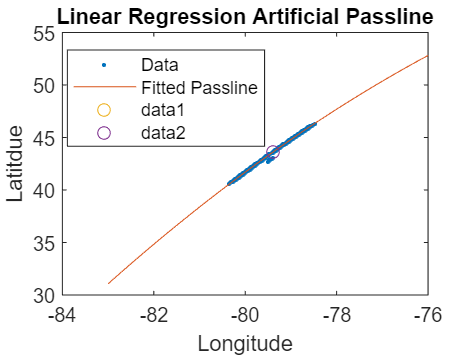

LAT_TOR = 43.6532;
LON_TOR = -79.3832;

hold on 
plot(LON_TOR, LAT_TOR, 'O')



save('beta.mat', "beta")